[status,sheets] = xlsfinfo('Khalid-Project-F2425.xls'); 
[A,names,raw] =xlsread('Khalid-Project-F2425.xls',1);
LN=length(names);
A; 
names;
raw; 
Absent=A(1:70);
N0=length(Absent);
Present=A(71:end);
N1=length(Present);
dat=[Absent;Present];
unsorted = [zeros(size(Absent));ones(size(Present))];
unsorted = [unsorted, dat];
sorted = sortrows(unsorted, 2, 'descend');
sorted = [sorted; 0,0];
T = sorted(:, 2);
counts = zeros(size(sorted));
[num_rows, num_cols] = size(counts);
for i = 1:num_rows
    Nc = 0;
    Nf = 0;
    if i == 0
        continue;
    else
        for j = 1:(i-1)
            if sorted(j, 1) == 1
                Nc = Nc + 1;
            else
                Nf = Nf + 1;
            end
        end
        counts(i, 1) = Nc;
        counts(i, 2) = Nf;
    end
end
P = zeros(size(counts));
for i = 1:131
    P(i, 1) = counts(i, 1)/N1;
    P(i, 2) = counts(i, 2)/N0;
end
dist = zeros(111,1);
for i = 1:111
    dist(i, 1) = pdist([0,1;P(i, 2), P(i, 1)],'euclidean');
end
[opt_dist, I] = min(dist);
P(I, :);
pf = P(:, 2);
pd = P(:, 1);

opt_thresh = T(I);
figure(1)
plot(pf,pd, 'r', 'LineWidth', 1.5)
hold on
plot(pf(I), pd(I), 'c*', 'MarkerSize', 8)
hold on
AUC = trapz(pf,pd);

pf_check = pf(I);
pd_check = pd(I);

intersect = [0.5, 0.74];
plot(intersect(1), intersect(2), 'sk', 'MarkerSize', 8)
intersect_dist = pdist([0,1;intersect(1), intersect(2)],'euclidean');
midpoint = [0.3667, 0.68];
plot(midpoint(1), midpoint(2), 'bo', 'MarkerSize', 8)
midpoint_dist = pdist([0,1;midpoint(1), midpoint(2)],'euclidean');

%Use Optimal as Threshold
threshold_op = 1.9343

threshold_op = 1.9343


NoTarget=xlsread('Khalid-Project-F2425.xls',1,'A1:A70');
Target=xlsread('Khalid-Project-F2425.xls',1,'A71:A130');

CorrectNoTargetDet = NoTarget < threshold_op;
NumCorrectNoTarget = sum(CorrectNoTargetDet);
CorrectTargetDet = Target > threshold_op;
NumCorrectTarget = sum(CorrectTargetDet);
FalseAlarm = NoTarget > threshold_op;
NumFalseAlarm = sum(FalseAlarm);
Miss = Target < threshold_op;
NumMiss = sum(Miss);

%Confusion Matrix
confusionMatrix_optimum = [NumCorrectNoTarget, NumMiss; NumFalseAlarm, NumCorrectTarget]

confusionMatrix_optimum =     47     7
    23    53



%Transition Matix
transitionMatrix_optimum = confusionMatrix_optimum*[1/70,0;0,1/60]

transitionMatrix_optimum =     0.6714    0.1167
    0.3286    0.8833



%A priori probability
apriori_op=[70/130;60/130];

%Output Vector, product of transition matrix and apriori gives the output
%probabilities
outputVector_op = transitionMatrix_optimum*apriori_op

outputVector_op =     0.4154
    0.5846



%Error Rate
errorRate_optimum = (NumFalseAlarm + NumMiss)/130

errorRate_optimum = 0.2308


%PPV
ppv_optimum = NumCorrectTarget/(NumFalseAlarm+NumCorrectTarget)

ppv_optimum = 0.6974

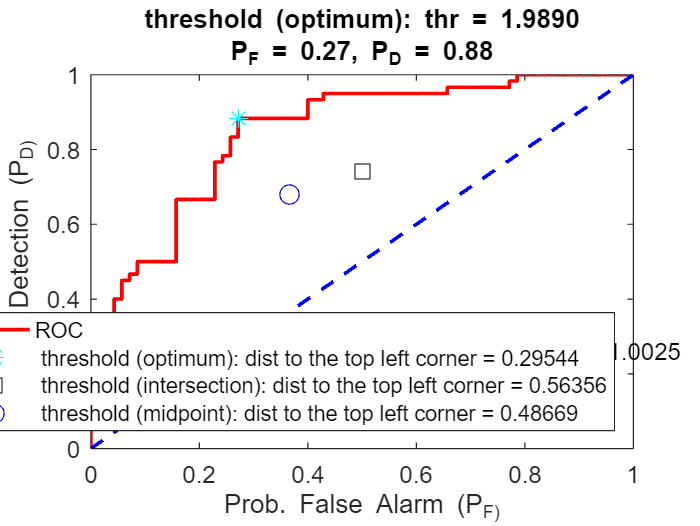


x = 0:0.01:1;
y = x;
plot(x,y,'b--', 'LineWidth', 1.5)
xlabel('Prob. False Alarm (P_F)'),ylabel('Prob. Detection (P_D)')
perf_idx = abs(mean(Absent) - mean(Present)) / sqrt(var(Absent) + var(Present));
txt = {[' AUC = ',num2str(AUC)], [' Perform. Index = ',num2str(perf_idx)]};
text(0.6, 0.3, txt)
legend('ROC', [' threshold (optimum): dist to the top left corner = ',num2str(opt_dist)],[' threshold (intersection): dist to the top left corner = ',num2str(intersect_dist)],[' threshold (midpoint): dist to the top left corner = ',num2str(midpoint_dist)],'Location','southeast')
title(sprintf('threshold (optimum): thr = %.4f\nP_F = %.2f, P_D = %.2f', opt_thresh, pf_check, pd_check));


x1=A(1:70,1);
x2=A(71:130,1);
figure(2)
xx=0:0.0001:1.2*max(x1);
xx1 = xx;fx1=ksdensity(x1,xx);
plot(xx,fx1,'r' ,'linewidth',1.5)
hold on
xlabel('input data'),ylabel('estimated pdf')
hold on 
xx=0:0.0001:1.2*max(x2);
fx2=ksdensity(x2,xx); 
plot(xx,fx2,'--k' ,'linewidth',1.5)

pm_check = 1 -pd_check

pm_check = 0.1167

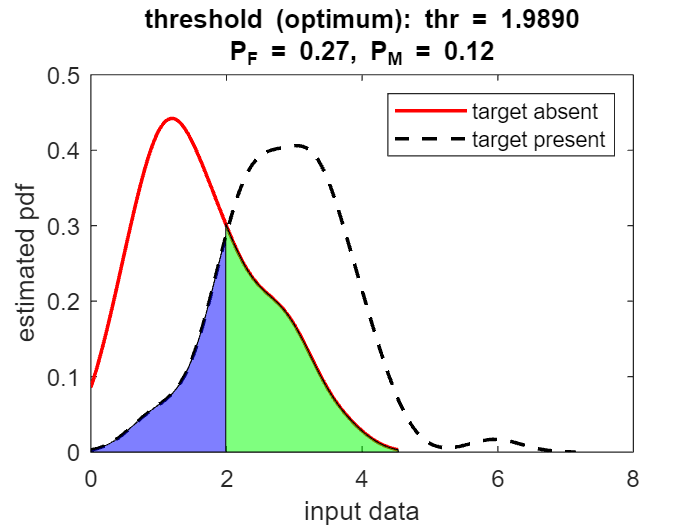


title(sprintf('threshold (optimum): thr = %.4f\nP_F = %.2f, P_M = %.2f', opt_thresh, pf_check, pm_check));
hold on
idx_1 = find(abs(xx1 - opt_thresh) < 0.00001);
X=[xx1(idx_1:end),fliplr(xx1(idx_1:end))];
Y=[fx1(idx_1:end),fliplr(fx1(idx_1:end) * 0)]; 
h1 = fill(X,Y,'g');
set(h1,'facealpha',.5)
idx_2 = find(abs(xx - opt_thresh) < 0.00001);
X=[xx(1:idx_2),fliplr(xx(1:idx_2))];
Y=[fx2(1:idx_2),fliplr(fx2(1:idx_2) * 0)];
h2 = fill(X,Y,'b');
set(h2,'facealpha',.5)
legend('target absent', 'target present')
hold off

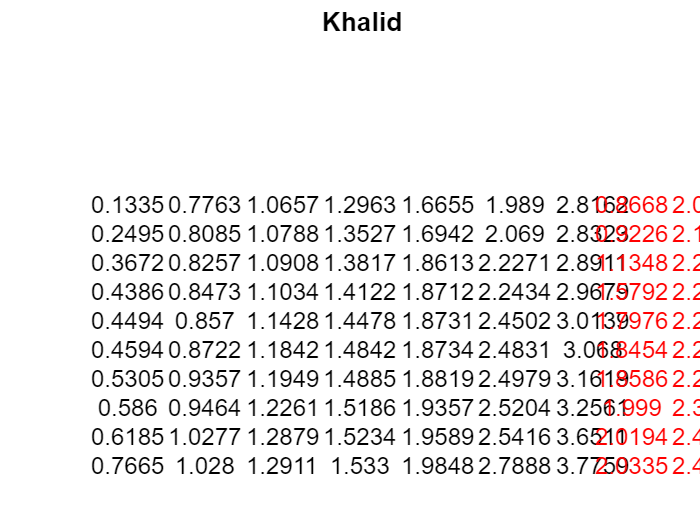

figure
xlim([0, 7]), ylim([0, 7]), axis off
hold on

Absent = sort(Absent);
Present = sort(Present);

% Verify data lengths
if mod(length(Absent), 7) ~= 0
    Absent(end+1:7*ceil(length(Absent)/7)) = NaN; % Pad with NaN
end
if mod(length(Present), 6) ~= 0
    Present(end+1:6*ceil(length(Present)/6)) = NaN; % Pad with NaN
end

dats_Absent = reshape(Absent, [], 7);
dats_Present = reshape(Present, [], 6);

title('Khalid')

for k = 1:7
    text((k - 1), 2.2, num2str(dats_Absent(:, k)))
end

% Remove the empty text() call
% text()

% Set axis limits only once
% xlim([0, 7]), ylim([0, 7]), axis off

for k = 1:6
    text(6.5 + (k - 1), 2.2, num2str(dats_Present(:, k)), 'color', 'r')
end


% Optionally, adjust the title
% title('Abdulwahab Data')
